# Lerner index calculation of selected market participants

## Load marginal cost and price data

load("../model_output/mat_files/MCPolyfitResults.mat");
load("../model_output/mat_files/selDateTimePriceISONE.mat");
load("../model_output/mat_files/PriceOrigFiltSeasons.mat");
load("../model_output/mat_files/MCSeasonFitResults.mat");

## Calculate Lerner index

selMCPriceTables = cell(numSelParts, 1);
quantLerner4Plots = cell(numSelParts, 1);
quadLernerModel = zeros(numSelParts, 3);
quadLernerS = cell(numSelParts, 1);
quadLernerMu = zeros(numSelParts, 2);
for n=1:size(selMCPriceTables, 1)
    selMCTable = selMCPolyfitTables{n};
    % Join with price table
    selMCPriceTable = outerjoin(selMCTable,selDateTimePrice,'Type','left','Keys',{'Date','Hour'},'MergeKeys',true, ...
        "LeftVariables",{'Awarded', 'MCMarket', 'MCQuadFit', 'MCCubicFit', 'Date', 'Hour'}, "RightVariables", {'averageLMP', 'CLFactor'});
    selMCPriceTable.LernerData = (selMCPriceTable.averageLMP - selMCPriceTable.MCMarket)./selMCPriceTable.averageLMP;
    % Quadratic fit of Lerner index
    [p, S, mu] = polyfit(selMCPriceTable.Awarded, selMCPriceTable.LernerData, 2);
    [y_fit, delta] = polyval(p, selMCPriceTable.Awarded, S, mu);
    selMCPriceTable.LernerQuad = y_fit;
    selMCPriceTables{n} = selMCPriceTable;
    quadLernerModel(n, :) = p;
    quadLernerS{n} = S;
    quadLernerMu(n, :) = mu;
    % Fitting data for plot
    quantity4Plot = [min(selMCPriceTable.Awarded):max(selMCPriceTable.Awarded)]';
    Lerner4Plot = polyval(p, quantity4Plot, S, mu);
    quantLerner4Plots{n} = [quantity4Plot, Lerner4Plot];
end

## Plot Lerner index

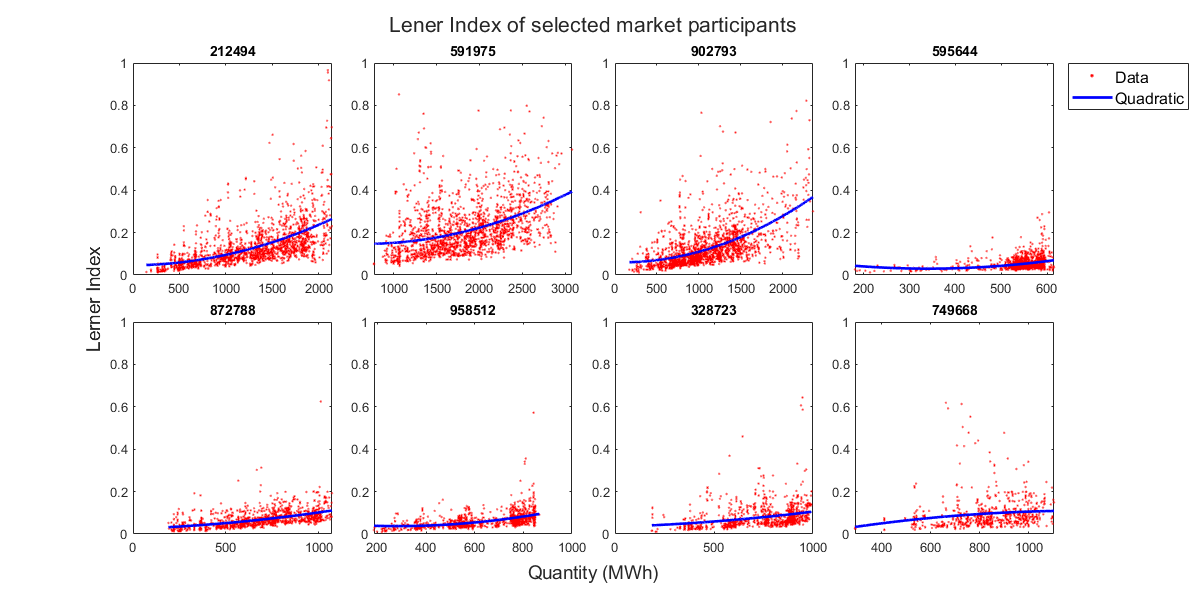

% Plot quantity vs marginal cost of selected market participants
plotColumn = 4;
t = tiledlayout(numSelParts/plotColumn, plotColumn, "TileSpacing","compact");
for n = 1:numSelParts
    nexttile;
    selMCPriceTable = selMCPriceTables{n};
    partID = selPartIDs(n);
    scatter(selMCPriceTable.Awarded, selMCPriceTable.LernerData, 10, 'r.');
    hold on;
    % Plot quadratic estimation
    quantity4Plot = quantLerner4Plots{n}(:, 1);
    Lerner4Plot = quantLerner4Plots{n}(:, 2);
    plot(quantity4Plot, Lerner4Plot, 'b-', "LineWidth", 2);
    hold off; box on;
    title(partID);
    ylim([0, 1]);
    if n==plotColumn
        legend(["Data", "Quadratic"], "Location","bestoutside", "FontSize", 12);
    end
end
xlabel(t, "Quantity (MWh)", "FontSize", 14);
ylabel(t, "Lerner Index", "FontSize", 14);
title(t, "Lener Index of selected market participants", "FontSize", 16);
set(gcf, "Position", [50, 50, 1200, 600]);
saveas(gcf, "../model_output/figures/LernerQuadPolyfit.png");

## Calculate Lerner Index of selected 4 market participants in 4 seasons

sel4LernerTableSeasons = cell(4, 4);
Lerner4PlotSeasons = cell(4, 4, 1);
quadLernerModelSeasons = zeros(4, 4, 3);
quadLernerSSeasons = cell(4, 4, 1);
quadLernerMuSeasons = zeros(4, 4, 2);
for n=1:4
    for s=1:4
        selMCTable = sel4PolyFitQMCSeason{n, s};
        priceTable = selPriceSeasons{s};
        % Join with price table
        LernerTable = outerjoin(selMCTable, priceTable, "Type", "left", "Keys", {'Date','Hour'}, "MergeKeys", true, ...
            "LeftVariables",{'Awarded', 'MCMarket', 'MCQuadFit', 'MCCubicFit', 'Date', 'Hour'},"RightVariables", {'averageLMP','CLFactor'});
        LernerTable.LernerData = (LernerTable.averageLMP - LernerTable.MCMarket)./LernerTable.averageLMP;
        % Quadratic fit of Lerner index
        [p, S, mu] = polyfit(LernerTable.Awarded, LernerTable.LernerData, 2);
        [y_fit, delta] = polyval(p, LernerTable.Awarded, S, mu);
        LernerTable.LernerQuadFit = y_fit;
        sel4LernerTableSeasons{n, s} = LernerTable;
        quadLernerModelSeasons(n, s, :) = p;
        quadLernerSSeasons{n, s} = S;
        quadLernerMuSeasons(n, s, :) = mu;
        % Fitting data for plot
        quantity4Plot = [min(LernerTable.Awarded):max(LernerTable.Awarded)]';
        Lerner4Plot = polyval(p, quantity4Plot, S, mu);
        Lerner4PlotSeasons{n, s} = [quantity4Plot, Lerner4Plot];        
    end
end

## Plot Lerner index of selected 4 market participants in 4 seasons

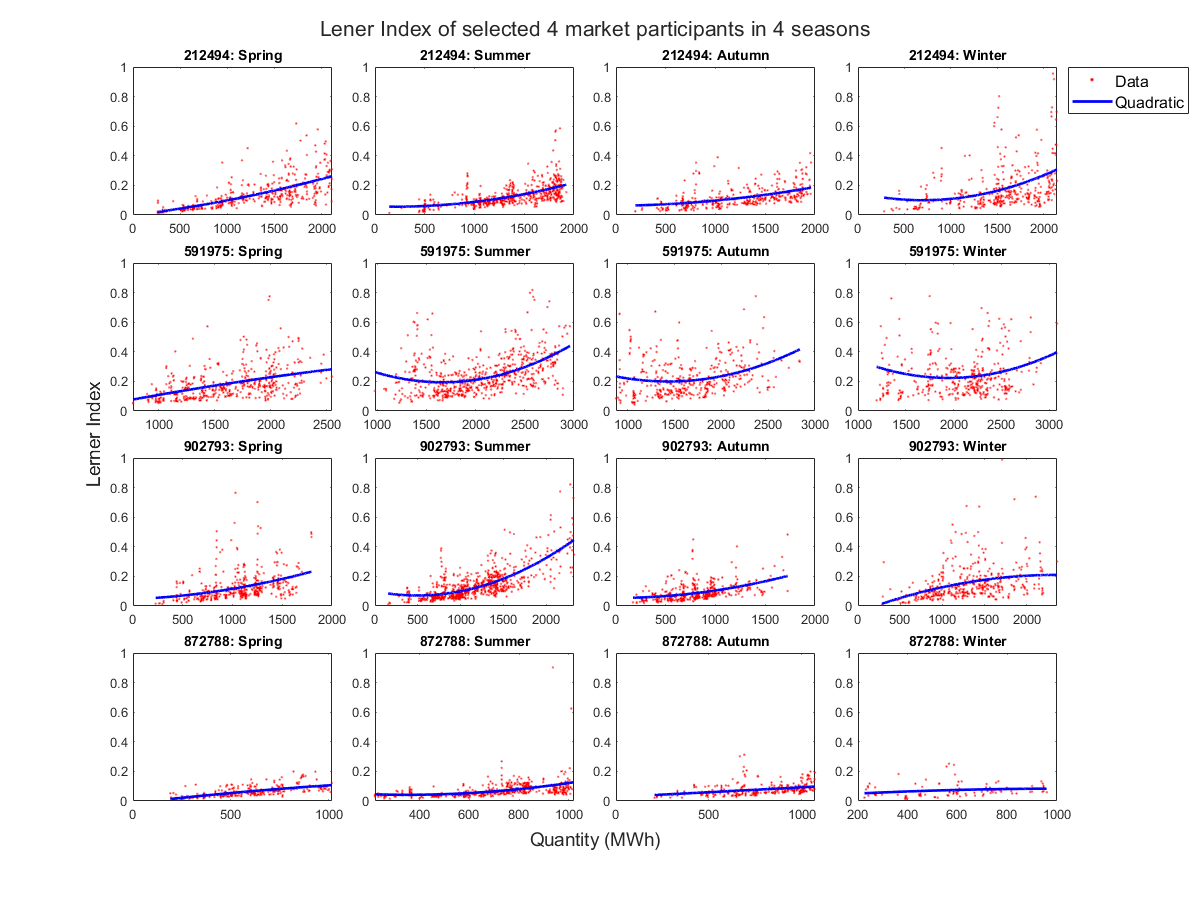

Seasons = ["Spring", "Summer", "Autumn", "Winter"];
t = tiledlayout(4, 4, "TileSpacing","compact");
for n=1:4
    for s=1:4
        nexttile;
        partID = sel4PartIDs(n);
        LernerTable = sel4LernerTableSeasons{n, s};
        hold on;
        % Plot Lerner Index data
        scatter(LernerTable.Awarded, LernerTable.LernerData, 10, 'r.');
        % Plot quadratic fit of Lerner Index
        plot(Lerner4PlotSeasons{n, s}(:, 1), Lerner4PlotSeasons{n, s}(:, 2), 'b-', "LineWidth", 2);
        hold off; box on;
        ylim([0, 1]);
        title(string(partID) + ": " + Seasons(s));
        if (n==1) && (s==4)
            legend(["Data", "Quadratic"], "Location","bestoutside", "FontSize", 12);
        end
    end
end
xlabel(t, "Quantity (MWh)", "FontSize", 14);
ylabel(t, "Lerner Index", "FontSize", 14);
title(t, "Lener Index of selected 4 market participants in 4 seasons", "FontSize", 16);
set(gcf, "Position", [50, 50, 1200, 900]);
saveas(gcf, "../model_output/figures/LernerSel4Seasons.png");

## Write Lerner index results to file

selLernerFitTables = selMCPriceTables;
save("../model_output/mat_files/LernerPolyfitResults.mat", "selLernerFitTables", "numSelParts", "selPartIDs", "-mat");
save("../model_output/mat_files/LernerPolyfitQuad.mat", "quadLernerModel", "quadLernerS", "quadLernerMu", "-mat");
save("../model_output/mat_files/LernerPolyfitSeasons.mat", "sel4LernerTableSeasons", "sel4PartIDs", "sel4PartIdx", "-mat");
save("../model_output/mat_files/LernerQuadModelSeasons.mat", "quadLernerModelSeasons", "quadLernerSSeasons", "quadLernerMuSeasons", "-mat");